# Logistic regression with basis functions

If we use basis functions to nonlinearly map our feature vectors to a new space, then logistic regression (with a linear discriminant) in this new space corresponds to using a nonlinear discriminant in the original space of our feature vectors. (Another way to have logistic regression and other linear classifiers use a nonlinear discriminant is to use kernel functions.)

In this demo, we'll use two-dimensional feature vectors and map them using basis functions to give us quadratic or cubic discriminants. The data set is two classes, with both classes being Gaussian with the same covariance matrix. Thus the optimal decision surface is linear. Thus quadratic and cubic basis functions will allow overfitting of the trained models to the data. You can extend this demo for a more complicated data set.

### Quadratic discriminants in two-dimensions

Generate 2-dimensional synthetic data in two classes.

n = 20;
x = [randn(n,2)-.8; randn(n,2)+.8];
y = [zeros(n,1); ones(n,1)];

Set the basis functions to give us a quadratic discriminant.

x1=x(:,1)'; % first component of data points
x2=x(:,2)'; % second component of data points x
phi = [ones(1,2*n)
       x1
       x2
       x1.*x1
       x1.*x2
       x2.*x2];
nll_fun = @(w) y'*log(1+exp(-w'*phi)') + (1-y)'*log(1+exp(w'*phi)');

Call the optimizer. The negative log likelihood function defined above will work for any number of dimensions.

w = fminunc(nll_fun, [0 0 0 0 0 0]')


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


w =    -1.4080
    4.6090
   14.5750
   -0.6544
  -11.4644
    7.1530


Compute the logistic function on a two-dimensional mesh.

xx = -4:.01:4;
yy = -4:.01:4;
[x1, x2] = meshgrid(xx, yy);
s = w(1) + w(2)*x1 + w(3)*x2 + w(4)*x1.*x1 + w(5)*x1.*x2 + w(6)*x2.*x2;
Z = 1./(1+exp(-s));

Plot the decision surface and the data points.

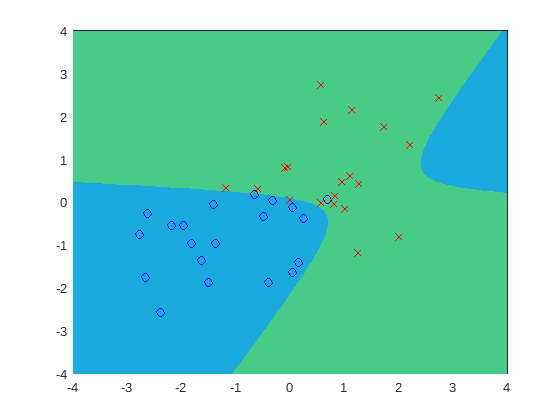

figure; clf
h = pcolor(xx, yy, sign(Z-0.5));
set(h, 'edgecolor', 'none');
caxis([-5 5]);
hold on
plot(x(1:n,1),x(1:n,2),'bo');
plot(x(n+1:2*n,1),x(n+1:2*n,2),'rx');

You can use "Run Section" in this live script to see the discriminants for other instances of the data. Keep in mind that the discriminants are generally overfitting the data.

### Cubic discriminants in two-dimensions

Generate data and set the basis functions to give us a cubic discriminant.

x = [randn(n,2)-.8; randn(n,2)+.8];
y = [zeros(n,1); ones(n,1)];

x1=x(:,1)'; % first component of data points
x2=x(:,2)'; % second component of data points x
phi = [ones(1,2*n)
       x1
       x2
       x1.*x1
       x1.*x2
       x2.*x2
       x1.^3
       x1.^2.*x2
       x1.*x2.^2
       x2.^3];
nll_fun = @(w) y'*log(1+exp(-w'*phi)') + (1-y)'*log(1+exp(w'*phi)');

Call the optimizer. We set the maximum number of function evaluations to 3000.

options = optimoptions('fminunc','MaxFunctionEvaluations',3000);
w = fminunc(nll_fun, [0 0 0 0 0 0 0 0 0 0]', options)


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


w =   -12.0474
  -10.9826
   20.0102
   10.4806
  -15.1606
   14.6891
   21.8532
   -4.7761
   16.0532
   12.0141


Compute the logistic function on a two-dimensional mesh.

xx = -4:.01:4;
yy = -4:.01:4;
[x1, x2] = meshgrid(xx, yy);
s = w(1) + w(2)*x1 + w(3)*x2 + w(4)*x1.*x1 + w(5)*x1.*x2 + w(6)*x2.*x2 ...
         + w(7)*x1.^3 + w(8)*x1.^2.*x2 + w(9)*x1.*x2.^2 + w(10)*x2.^3;
Z = 1./(1+exp(-s));

Plot the decision surface. For fun, we'll plot it in a more colorful way than we did above.

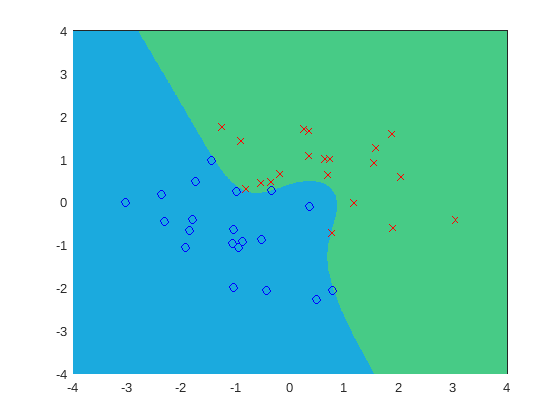

figure; clf
h = pcolor(xx, yy, sign(Z-0.5));
set(h, 'edgecolor', 'none');
caxis([-5 5]);
hold on
plot(x(1:n,1),x(1:n,2),'bo');
plot(x(n+1:2*n,1),x(n+1:2*n,2),'rx');

You can use "Run Section" in this live script to see the discriminants for other instances of the data. Again, keep in mind that the discriminants are generally overfitting the data.

### Taking it further

Generate some more complicated data, i.e., one that is ideally separated by a quadratic or cubic discriminant, rather than a linear one. See how the above algorithms work on your data.